**EE 150**

**Signals and Systems**

** Lab 6 Laplace Transform**

Date Performed: 2022.12.8

Class Id: Thur_105

Name & ID: 王鹏豪_2021533138_周守琛_2021533042

1. $F\left(s\right)=\frac{s^3 +5s^2 +9s+7}{s^2 +3s+2}$, find out the inverse Laplace transform of F(s).

syms s
F = (s^3 + 5*s^2 + 9*s + 7)/(s^2 + 3*s + 2);
ft = ilaplace(F)

$$ft = 2\,{\mathrm{e}}^{-t}-{\mathrm{e}}^{-2\,t}+2\,\delta (t)+\delta^{\prime }(t)$$

2. $y^{\prime \prime } \left(t\right)+4y^{\prime } \left(t\right)+4y\left(t\right)=f^{\prime } \left(t\right)+3f\left(t\right),f\left(t\right)=e^{-t} u\left(t\right),y\left(0_+ \right)=0,y^{\prime } \left(0_+ \right)=1$. Find out the zero-state response by using Laplace transform and inverse Laplace transform. Plot the incentive and response in the same figure. 

clear;
clf;

syms t s
Hs = (s+3) / (s^2 + 4*s + 4);
ft = exp(-t).*heaviside(t);
Fs = laplace(ft);
Ys = Fs*Hs;
yt = ilaplace(Ys)

$$yt = 2\,{\mathrm{e}}^{-t}-2\,{\mathrm{e}}^{-2\,t}-t\,{\mathrm{e}}^{-2\,t}$$

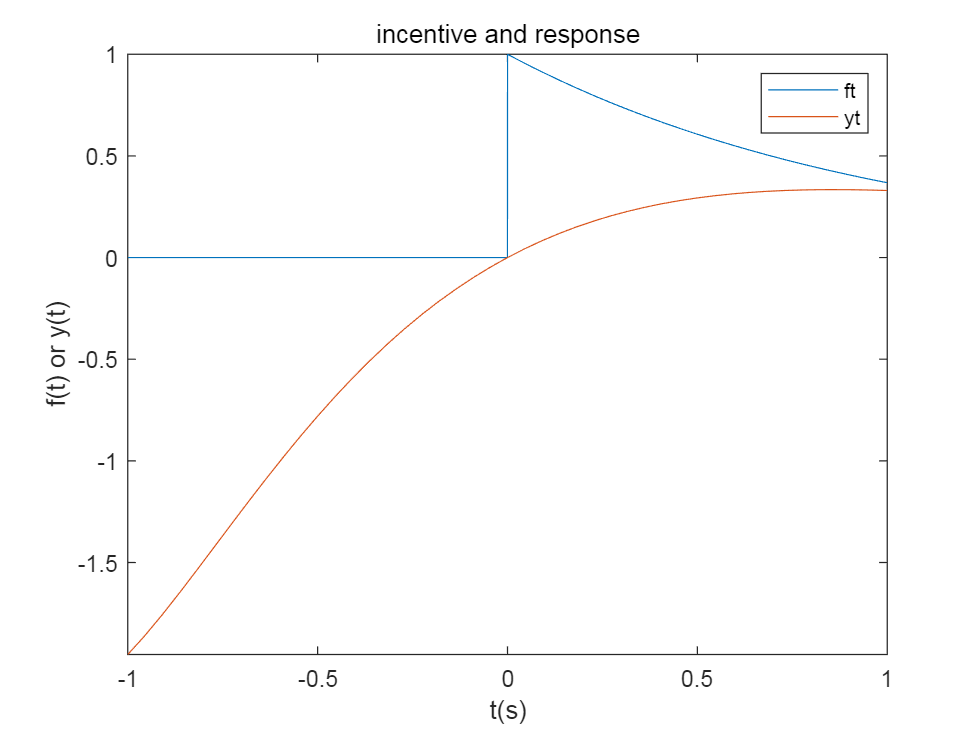

fplot(ft); hold on;
fplot(yt); hold off;
xlim([-1 1]);
legend(["ft", "yt"]);
title("incentive and response");
xlabel("t(s)");
ylabel("f(t) or y(t)");

3. $f\left(t\right)=\sin \left(t\right)u\left(t\right)$. Find out the Laplace transform of f(t). Draw the surface plot of magnitude, phase, real part and imaginary part in a 2*2 subplot. 

clear;
clf;

syms t
x = -1:0.06:1;y=x;
[sigma,omega] = meshgrid(x,y);
ss = sigma+1j*omega;

ft = sin(t).*heaviside(t);
F_s = laplace(ft)

$$F\_s = \frac{1}{s^{2}+1}$$

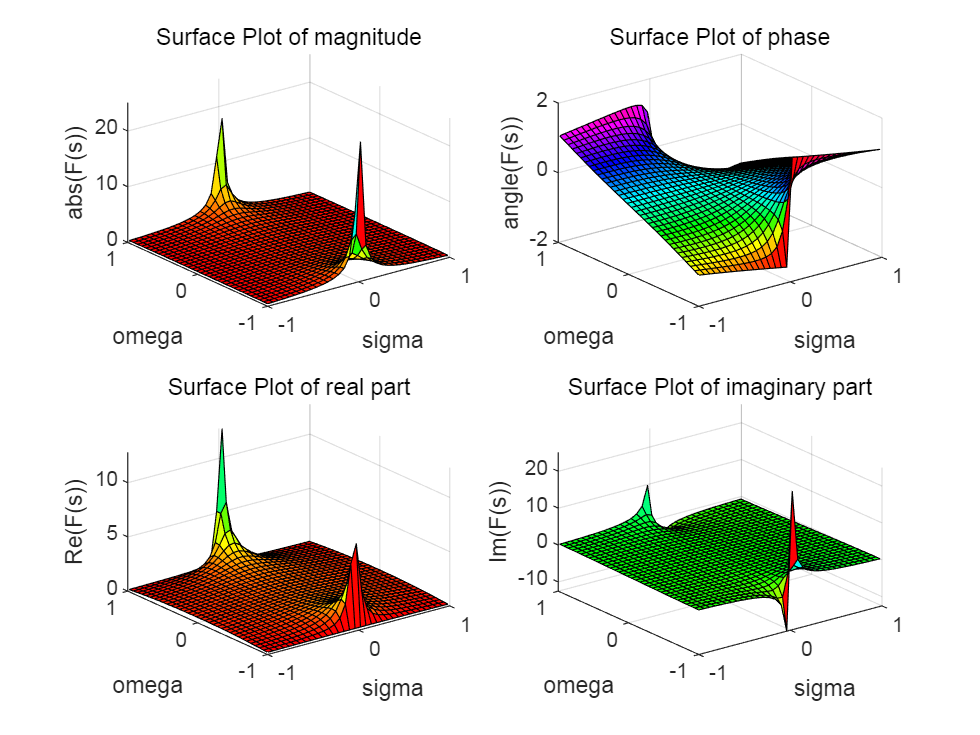


Fs = 1 ./ (ss.*ss+1);

subplot(2,2,1);
Fsabs = abs(Fs);
surf(sigma,omega,Fsabs);
%axis([-6,6,-6,6,0,2]);
xlabel('sigma');ylabel('omega');zlabel('abs(F(s))')
title("Surface Plot of magnitude");
colormap(hsv);
rotate3d on;

subplot(2,2,2);
Fsangle = angle(Fs);
surf(sigma,omega,Fsangle);
%axis([-6,6,-6,6,0,4.5]);
xlabel('sigma');ylabel('omega');zlabel('angle(F(s))')
title("Surface Plot of phase");
colormap(hsv);
rotate3d on;

subplot(2,2,3);
Fsreal = real(Fs);
surf(sigma,omega,Fsreal);
%axis([-6,6,-6,6,0,2]);
xlabel('sigma');ylabel('omega');zlabel('Re(F(s))')
title("Surface Plot of real part");
colormap(hsv);
rotate3d on;

subplot(2,2,4);
Fsimag = imag(Fs);
surf(sigma,omega,Fsimag);
%axis([-6,6,-6,6,0,2]);
xlabel('sigma');ylabel('omega');zlabel('Im(F(s))')
title("Surface Plot of imaginary part");
colormap(hsv);
rotate3d on;

4. $\mathrm{H12}\left(s\right)=\frac{1}{s^2 },\mathrm{H22}\left(s\right)=\frac{1}{{\left(s+2\right)}^2 },\mathrm{H32}\left(s\right)=\frac{1}{{\left(s-2\right)}^2 }$. 

a. Plot the poles and impulse response of the system. (adjust the diaplay range properly)

b. Find out whether the system is stable or not.

a.

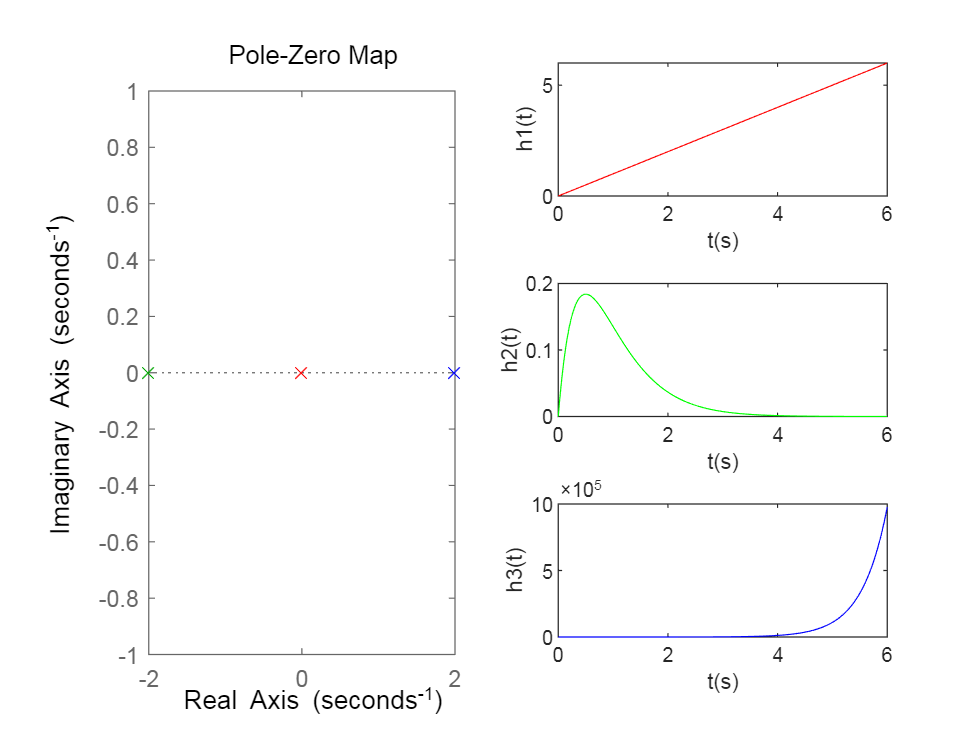

clear;
clf;

syms s
t = 0:0.001:6;
b = 1;
a = [1 0 0;1 4 4; 1 -4 4];
color = ["r","g","b"];
subplot(3,2,[1 3 5]); hold on;
for i=1:3
    sys = tf(b,a(i,:));
    pzplot(sys,color(i));
    ylim([-1 1]);
end
for i =1:3
    sys = tf(b,a(i,:));
    subplot(3,2,i*2); plot(t,impulse(sys,t),color(i));
    xlabel('t(s)');
    ylabel("h"+num2str(i)+"(t)");
end

b. 

If a continuous system is stable, all the poles of H(s) should be on the left half-plane of s-plane.

And only H22(s) fits that.

So the h1(H12(s)) and h3(H32(s)) is not stable.

    The h2(H22(s)) is stable.

 5. $f\left(t\right)=e^{-t} \sin \left(10t\right)u\left(t\right)$, plot the 3D surface of Laplace transform and the graph of Fourier transform. Adjust range of the axis and the observation angle of the 3D surface. Compare the two figures to confirm the relationship between Laplace transform and Fourier Transform.

clear;
clf;

syms t
t0 = 0:0.03:10;
x = -20:0.48:20;y=x;
[sigma,omega] = meshgrid(x,y);
s = sigma+1j*omega;

ft = exp(-t)*sin(10*t)*heaviside(t);

F_s = laplace(ft)

$$F\_s = \frac{10}{{\left(s+1\right)}^{2}+100}$$

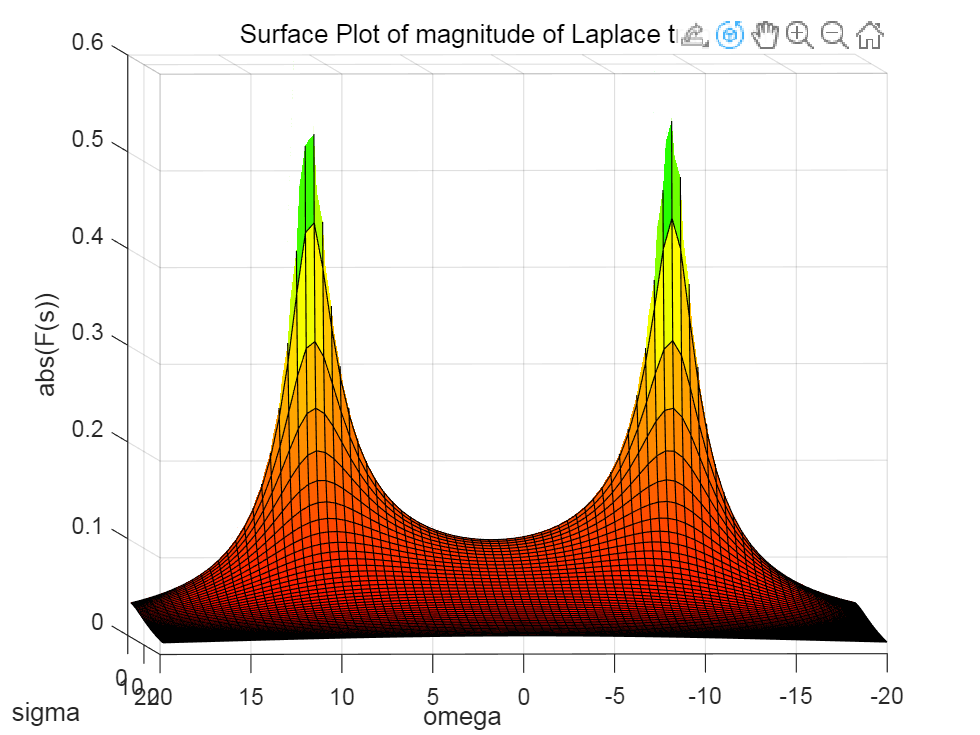

Fs = 10 ./ ((s+1).*(s+1) + 100);

Fsabs = abs(Fs);
surf(sigma,omega,Fsabs);
%axis([-6,0,-6,6,0,0.2]);
%xlim([-20, 0])
xlim([0, 20]);
zlim([0 0.6]);
xlabel('sigma');ylabel('omega');zlabel('abs(F(s))')
title("Surface Plot of magnitude of Laplace transform");
colormap(hsv);
rotate3d on;

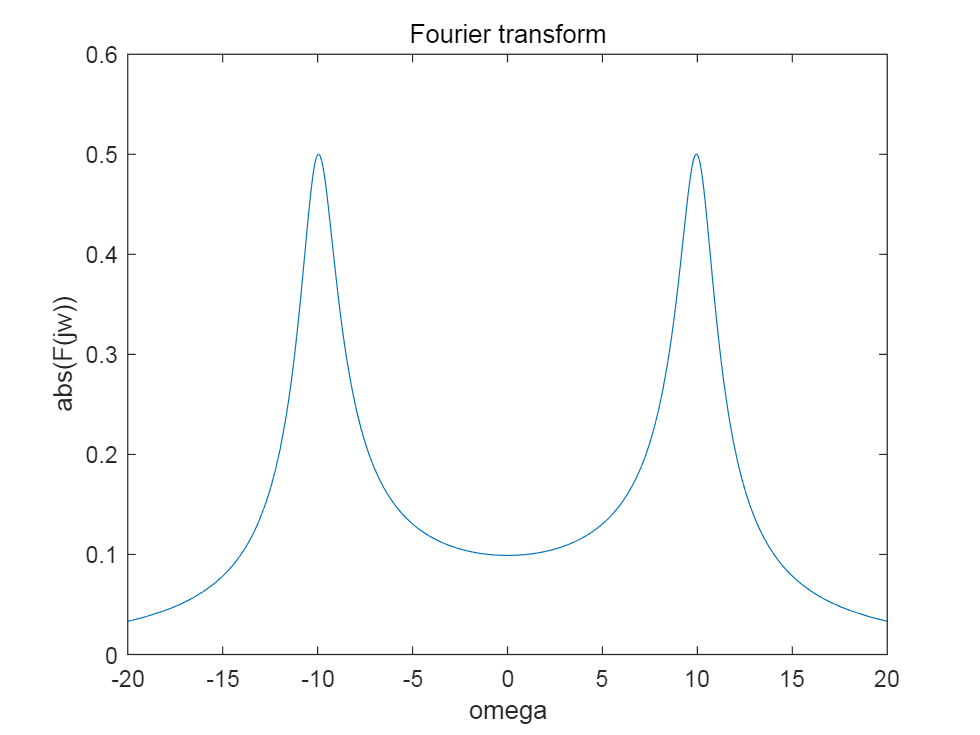


fplot(abs(fourier(ft)))
axis([-20,20,0,0.6])
xlabel("omega");
ylabel("abs(F(jw))");
title("Fourier transform");

when the Laplace tranform's  sigma = 0, it has the same has the same shape of the Fourier transform's figure.